% Clear workspace
clc;
clear;
close all;

% Define the robot using DH parameters (4 DOF)
% Each Link represents a joint with its parameters: [theta d a alpha]
L(1) = Link([0 0.5 0 pi/2]);  % Base to Link 1
L(2) = Link([0 0 1.3 0]);     % Link 1 to Link 2
L(3) = Link([0 0 1.6 0]);     % Link 2 to Link 3
L(4) = Link([0 0 1 0]);       % Link 3 to End-Effector (Fork)

% Create the robot model
Robot = SerialLink(L, 'name', 'Forklift Robot');

% Define joint angles (pose configuration in radians)
theta1 = 0;             % Base rotation
theta2 = 7/20 * pi;     % Lower the arm
theta3 = -5/6 * pi;     % Adjust to keep the fork horizontal
theta4 = 29/60 * pi;    % Fork rotation

% Define joint velocities (in rad/s)
joint_velocities = [0.1; 0.2; -0.1; 0.15];  % Example velocities for each joint

% Compute the Jacobian at the given joint configuration
J = Robot.jacob0([theta1, theta2, theta3, theta4]);

% Compute the end-effector velocity
% Linear velocity (v) and angular velocity (ω) in the base frame
end_effector_velocity = J * joint_velocities;

% Split into linear and angular velocities
linear_velocity = end_effector_velocity(1:3);  % Linear velocity (vx, vy, vz)
angular_velocity = end_effector_velocity(4:6); % Angular velocity (wx, wy, wz)

% Display results
disp('Jacobian Matrix (6x4):');

Jacobian Matrix (6x4):


disp(J);

    0.0000    0.4395    1.5978    0.0000
    1.6739    0.0000    0.0000    0.0000
         0    1.6739    1.0837    1.0000
    0.0000         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000



disp('Joint Velocities (rad/s):');

Joint Velocities (rad/s):


disp(joint_velocities);

    0.1000
    0.2000
   -0.1000
    0.1500



disp('End-Effector Velocity (linear and angular):');

End-Effector Velocity (linear and angular):


disp(end_effector_velocity);

   -0.0719
    0.1674
    0.3764
    0.0000
   -0.2500
    0.1000



disp('Linear Velocity (vx, vy, vz):');

Linear Velocity (vx, vy, vz):


disp(linear_velocity);

   -0.0719
    0.1674
    0.3764



disp('Angular Velocity (wx, wy, wz):');

Angular Velocity (wx, wy, wz):


disp(angular_velocity);

    0.0000
   -0.2500
    0.1000



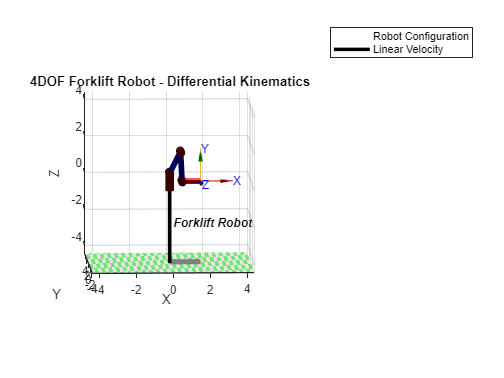


% Visualization
figure;
Robot.plot([theta1, theta2, theta3, theta4]);  % Plot the robot
title('4DOF Forklift Robot - Differential Kinematics');

% Add velocity annotations
hold on;
quiver3(0, 0, 0, linear_velocity(1), linear_velocity(2), linear_velocity(3), ...
    'r', 'LineWidth', 2, 'MaxHeadSize', 0.5); % Linear velocity vector
legend('Robot Configuration', 'Linear Velocity');